clc; close all; clear all;
s = tf('s');
P = [exp(-2*s)/(s+20) exp(-3*s)/(s-2); exp(-0.5*s)/(s-21) exp(-0.2*s)/(s+0.01)]

P =
 
  From input 1 to output...
                     1
   1:  exp(-2*s) * ------
                   s + 20
 
                       1
   2:  exp(-0.5*s) * ------
                     s - 21
 
  From input 2 to output...
                     1
   1:  exp(-3*s) * -----
                   s - 2
 
                        1
   2:  exp(-0.2*s) * --------
                     s + 0.01
 
Continuous-time transfer function.


Ts = 0.1;


%0.4/Ts % <---- verifica Ts para que la division see entero

PNDz = c2d(P,Ts,'zoh')

PNDz =
 
  From input 1 to output...
                  0.04323
   1:  z^(-20) * ----------
                 z - 0.1353
 
                 0.3412
   2:  z^(-5) * ---------
                z - 8.166
 
  From input 2 to output...
                  0.1107
   1:  z^(-30) * ---------
                 z - 1.221
 
                 0.09995
   2:  z^(-2) * ---------
                z - 0.999
 
Sample time: 0.1 seconds
Discrete-time transfer function.


PNDz = absorbDelay(PNDz);
Gss = ss(PNDz)

Gss =
 
  A = 
            x1      x2      x3      x4      x5      x6      x7      x8      x9     x10     x11     x12     x13     x14     x15     x16     x17     x18     x19     x20     x21     x22     x23     x24     x25     x26     x27     x28     x29     x30     x31     x32     x33     x34     x35     x36     x37     x38     x39     x40     x41     x42     x43     x44     x45     x46     x47     x48     x49     x50     x51     x52     x53     x54     x55     x56     x57     x58     x59     x60     x61
   x1   0.1353       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0    

A = Gss.A;
B = Gss.B;
C = Gss.C

C =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.6917         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    0.6825         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

D = Gss.D

D =      0     0
     0     0


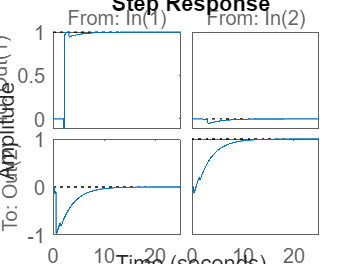


Qy = diag([100 1]);
Q = C'*Qy*C;
R = 0.1;

K = dlqr(A,B,Q,R);
nx = size(A,1);

Kr=(-(C-D*K)*((A-B*K-eye(nx))\B)+D)^-1;
step(ss(A-B*K,B*Kr,C-D*K,D*Kr,Ts))

clc; close all; clear all;
s = tf('s');
P = [exp(-2*s)/(s+20) exp(-3*s)/(s-2); exp(-0.5*s)/(s-21) exp(-0.2*s)/(s+0.01)]

P =
 
  From input 1 to output...
                     1
   1:  exp(-2*s) * ------
                   s + 20
 
                       1
   2:  exp(-0.5*s) * ------
                     s - 21
 
  From input 2 to output...
                     1
   1:  exp(-3*s) * -----
                   s - 2
 
                        1
   2:  exp(-0.2*s) * --------
                     s + 0.01
 
Continuous-time transfer function.


Ts = 0.1;


%0.4/Ts % <---- verifica Ts para que la division see entero

PNDz = c2d(P,Ts,'zoh')

PNDz =
 
  From input 1 to output...
                  0.04323
   1:  z^(-20) * ----------
                 z - 0.1353
 
                 0.3412
   2:  z^(-5) * ---------
                z - 8.166
 
  From input 2 to output...
                  0.1107
   1:  z^(-30) * ---------
                 z - 1.221
 
                 0.09995
   2:  z^(-2) * ---------
                z - 0.999
 
Sample time: 0.1 seconds
Discrete-time transfer function.


PNDz = absorbDelay(PNDz);
Gss = ss(PNDz)

Gss =
 
  A = 
            x1      x2      x3      x4      x5      x6      x7      x8      x9     x10     x11     x12     x13     x14     x15     x16     x17     x18     x19     x20     x21     x22     x23     x24     x25     x26     x27     x28     x29     x30     x31     x32     x33     x34     x35     x36     x37     x38     x39     x40     x41     x42     x43     x44     x45     x46     x47     x48     x49     x50     x51     x52     x53     x54     x55     x56     x57     x58     x59     x60     x61
   x1   0.1353       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0       0    

A = Gss.A;
B = Gss.B;
C = Gss.C;
D = Gss.D

D =      0     0
     0     0


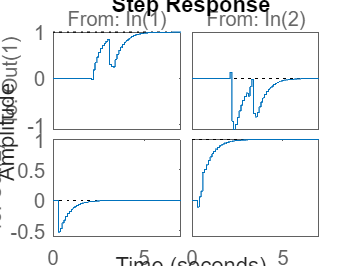



Qy = diag([1 100]);
Q = C'*Qy*C;
R = 0.1;

K = dlqr(A,B,Q,R);
nx = size(A,1);

Kr=(-(C-D*K)*((A-B*K-eye(nx))\B)+D)^-1;
step(ss(A-B*K,B*Kr,C-D*K,D*Kr,Ts))